## Load data

clear; clc; close all;

% m: misalign / a: align
load_path = "data\raw_data\Testbed_data";
save_path = "new_folder";

outer_m   = load(load_path+"\outer_m.mat");
inner_m   = load(load_path+"\inner_m.mat");
ball_m   = load(load_path+"\ball_m.mat");
normal_m = load(load_path+"\normal_m.mat");
outer_a   = load(load_path+"\outer_a.mat");
inner_a   = load(load_path+"\inner_a.mat");
ball_a   = load(load_path+"\ball_a.mat");
normal_a = load(load_path+"\normal_a.mat");

outer_m = outer_m.Acceleration;
inner_m = inner_m.Acceleration4;
ball_m = ball_m.Acceleration6;
normal_m = normal_m.Acceleration2;
outer_a = outer_a.Acceleration1;
inner_a = inner_a.Acceleration5;
ball_a = ball_a.Acceleration7;
normal_a = normal_a.Acceleration3;

## Outer(Misalignment) 클래스 이미지로 저장

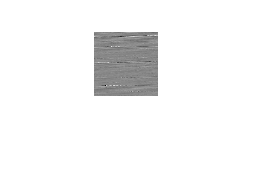

images = zeros(64,64);


images_size = 4096;
image_num = 125;

scaling = floor((outer_m - min(outer_m)) / (max(outer_m) - min(outer_m))*255) ;




for i = 1:image_num
    if i == 1
        images = reshape(uint8(scaling(1:images_size)),[64,64])';
    else
        images = reshape(uint8(scaling(i*900 + 1 : (i*900)+ 4096)),[64,64])';
    end
    imshow(images);
    imwrite(images,strcat(save_path+"/O2_img_data_",num2str(i),".jpg"),"JPG");
end